# Data preparation

clc
clearvars
close all

exp_num = "exp51";
calib_dir = strcat("calib_",exp_num);

meta_info1 = readtable("meta_info_wt.csv");
meta_info2 = readtable("meta_info_ko.csv");

current_names = {'iktof','ikslow1','ikslow2','ikss'};
tune_idx = cell(5,1);
tune_idx{1} = [1, 2, 4, 5, 7, 11, 13];
tune_idx{2} = [2, 3];
tune_idx{3} = [1, 2, 4, 5, 9, 10 11];
tune_idx{4} = [2, 3];
tune_idx{5} = [1, 2, 3, 4];
[mdl_struct,psize] = gen_mdl_struct(current_names,tune_idx);

[weeks1,sol_container1] = read_sol(meta_info1,mdl_struct,psize, ...
    strcat("calib_",exp_num,"/wt"));
[weeks2,sol_container2] = read_sol(meta_info2,mdl_struct,psize, ...
    strcat("calib_",exp_num,"/mgat1ko"));

# Simple univariate plots

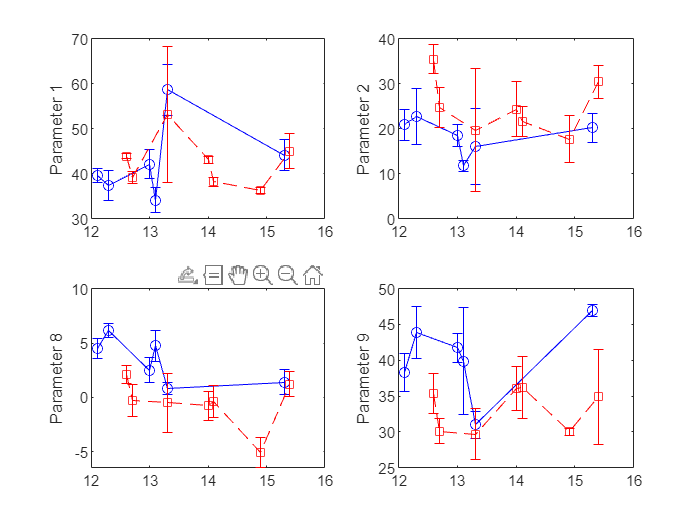

idx_group1 = [1,2,8,9];
idx_group2 = [3,4,10,11,17];
idx_group3 = [5,6,18];
idx_group4 = [12,13,15,19];
idx_group5 = [7,14,16,20];

pmean1 = NaN(length(weeks1),length(idx_group1));
perr1 = NaN(length(weeks1),length(idx_group1));
pmean2 = NaN(length(weeks2),length(idx_group1));
perr2 = NaN(length(weeks2),length(idx_group1));

for i=1:length(weeks1)
    for j=1:length(idx_group1)
        pmean1(i,j) = mean(sol_container1{i}(:,idx_group1(j)));
        perr1(i,j) = std(sol_container1{i}(:,idx_group1(j)))/sqrt(size(sol_container1{i},1));
    end
end

for i=1:length(weeks2)
    for j=1:length(idx_group1)
        pmean2(i,j) = mean(sol_container2{i}(:,idx_group1(j)));
        perr2(i,j) = std(sol_container2{i}(:,idx_group1(j)))/sqrt(size(sol_container2{i},1));
    end
end

for i=1:length(idx_group1)
    subplot(2,2,i)
    errorbar(weeks1,pmean1(:,i),perr1(:,i),'-o','Color','blue')
    hold on
    errorbar(weeks2,pmean2(:,i),perr2(:,i),'--s','Color','red')
    ylabel(strcat("Parameter ",num2str(idx_group1(:,i))))
    hold off
end

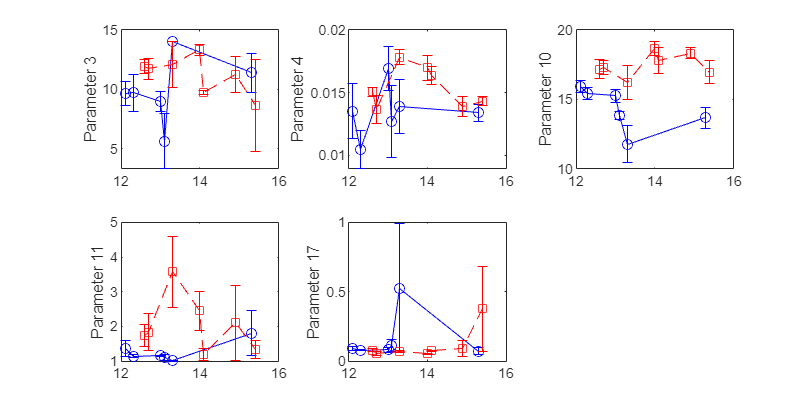

pmean1 = NaN(length(weeks1),length(idx_group2));
perr1 = NaN(length(weeks1),length(idx_group2));
pmean2 = NaN(length(weeks2),length(idx_group2));
perr2 = NaN(length(weeks2),length(idx_group2));

for i=1:length(weeks1)
    for j=1:length(idx_group2)
        pmean1(i,j) = mean(sol_container1{i}(:,idx_group2(j)));
        perr1(i,j) = std(sol_container1{i}(:,idx_group2(j)))/sqrt(size(sol_container1{i},1));
    end
end

for i=1:length(weeks2)
    for j=1:length(idx_group2)
        pmean2(i,j) = mean(sol_container2{i}(:,idx_group2(j)));
        perr2(i,j) = std(sol_container2{i}(:,idx_group2(j)))/sqrt(size(sol_container2{i},1));
    end
end

figure('Position',[10,10,840,420])
for i=1:length(idx_group2)
    subplot(2,3,i)
    errorbar(weeks1,pmean1(:,i),perr1(:,i),'-o','Color','blue')
    hold on
    errorbar(weeks2,pmean2(:,i),perr2(:,i),'--s','Color','red')
    hold off
    ylabel(strcat("Parameter ",num2str(idx_group2(:,i))))
end

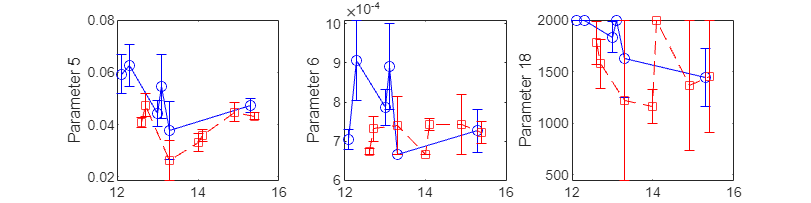

pmean1 = NaN(length(weeks1),length(idx_group3));
perr1 = NaN(length(weeks1),length(idx_group3));
pmean2 = NaN(length(weeks2),length(idx_group3));
perr2 = NaN(length(weeks2),length(idx_group3));

for i=1:length(weeks1)
    for j=1:length(idx_group3)
        pmean1(i,j) = mean(sol_container1{i}(:,idx_group3(j)));
        perr1(i,j) = std(sol_container1{i}(:,idx_group3(j)))/sqrt(size(sol_container1{i},1));
    end
end

for i=1:length(weeks2)
    for j=1:length(idx_group3)
        pmean2(i,j) = mean(sol_container2{i}(:,idx_group3(j)));
        perr2(i,j) = std(sol_container2{i}(:,idx_group3(j)))/sqrt(size(sol_container2{i},1));
    end
end

figure('Position',[10,10,840,210])
for i=1:length(idx_group3)
    subplot(1,3,i)
    errorbar(weeks1,pmean1(:,i),perr1(:,i),'-o','Color','blue')
    hold on
    errorbar(weeks2,pmean2(:,i),perr2(:,i),'--s','Color','red')
    hold off
    ylabel(strcat("Parameter ",num2str(idx_group3(:,i))))
end

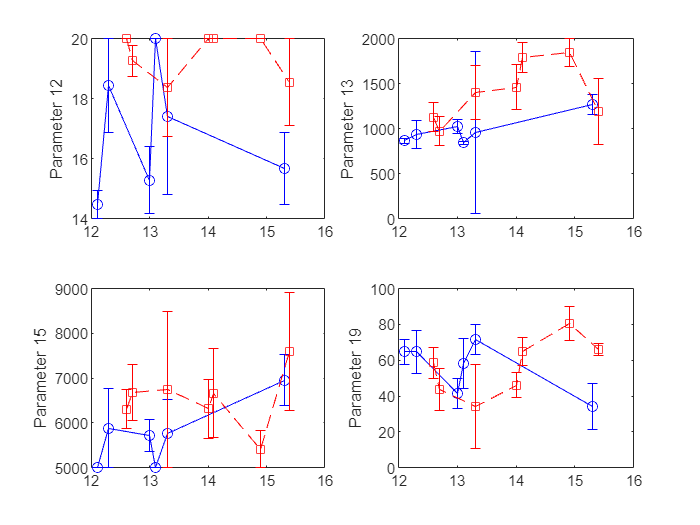

pmean1 = NaN(length(weeks1),length(idx_group4));
perr1 = NaN(length(weeks1),length(idx_group4));
pmean2 = NaN(length(weeks2),length(idx_group4));
perr2 = NaN(length(weeks2),length(idx_group4));

for i=1:length(weeks1)
    for j=1:length(idx_group4)
        pmean1(i,j) = mean(sol_container1{i}(:,idx_group4(j)));
        perr1(i,j) = std(sol_container1{i}(:,idx_group4(j)))/sqrt(size(sol_container1{i},1));
    end
end

for i=1:length(weeks2)
    for j=1:length(idx_group4)
        pmean2(i,j) = mean(sol_container2{i}(:,idx_group4(j)));
        perr2(i,j) = std(sol_container2{i}(:,idx_group4(j)))/sqrt(size(sol_container2{i},1));
    end
end

figure('Position',[10,10,560,420])
for i=1:length(idx_group4)
    subplot(2,2,i)
    errorbar(weeks1,pmean1(:,i),perr1(:,i),'-o','Color','blue')
    hold on
    errorbar(weeks2,pmean2(:,i),perr2(:,i),'--s','Color','red')
    hold off
    ylabel(strcat("Parameter ",num2str(idx_group4(:,i))))
end

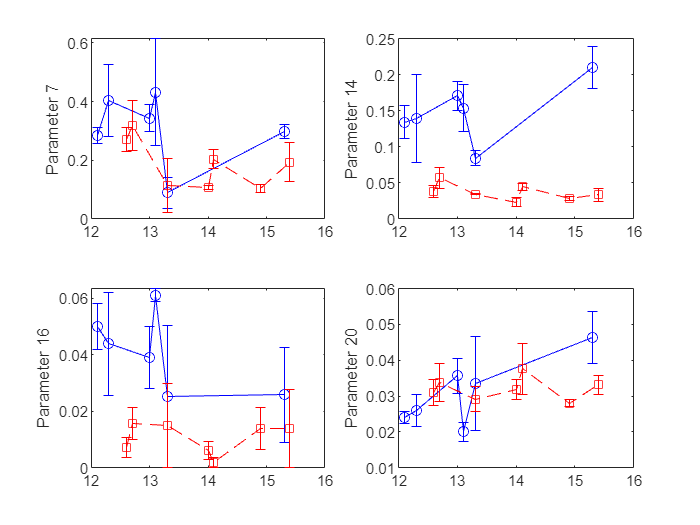

pmean1 = NaN(length(weeks1),length(idx_group5));
perr1 = NaN(length(weeks1),length(idx_group5));
pmean2 = NaN(length(weeks2),length(idx_group5));
perr2 = NaN(length(weeks2),length(idx_group5));

for i=1:length(weeks1)
    for j=1:length(idx_group5)
        pmean1(i,j) = mean(sol_container1{i}(:,idx_group5(j)));
        perr1(i,j) = std(sol_container1{i}(:,idx_group5(j)))/sqrt(size(sol_container1{i},1));
    end
end

for i=1:length(weeks2)
    for j=1:length(idx_group5)
        pmean2(i,j) = mean(sol_container2{i}(:,idx_group5(j)));
        perr2(i,j) = std(sol_container2{i}(:,idx_group5(j)))/sqrt(size(sol_container2{i},1));
    end
end

figure('Position',[10,10,560,420])
for i=1:length(idx_group5)
    subplot(2,2,i)
    errorbar(weeks1,pmean1(:,i),perr1(:,i),'-o','Color','blue')
    hold on
    errorbar(weeks2,pmean2(:,i),perr2(:,i),'--s','Color','red')
    hold off
    ylabel(strcat("Parameter ",num2str(idx_group5(:,i))))
end

function [mdl_struct, psize] = gen_mdl_struct(current_names,tune_idx)
    num_currents = length(current_names);
    
    % index 1
    idx_info1 = cell(1,num_currents);
    for i = 1:num_currents
        switch current_names{i}
            case 'iktof'
                idx_info1{i} = tune_idx{1};
            case 'iktos'
                idx_info1{i} = tune_idx{2};
            case 'ikslow1'
                idx_info1{i} = tune_idx{3};
            case 'ikslow2'
                idx_info1{i} = tune_idx{4};
            case 'ikss'
                idx_info1{i} = tune_idx{5};
        end
    end

    % index 2
    idx_info2 = cell(1,num_currents);
    psize = 0;
    for i = 1: num_currents
        psize_old = psize;
        psize = psize + length(idx_info1{i});
        idx_info2{i} = (1+psize_old):(psize);
    end

    model_info = [current_names; idx_info1; idx_info2];
    field_names = ["name","idx1","idx2"];
    mdl_struct = cell2struct(model_info, field_names, 1);    
end

function sol = gen_sol_vec(sol_mx, model_struct, psize)
    sol = zeros(1, psize);
    for i = 1:length(model_struct)
        running_sol = sol_mx(:, i);
        running_sol = running_sol(~isnan(running_sol));
        sol(model_struct(i).idx2) = running_sol(model_struct(i).idx1);
    end
end

function [weeks,sol_container] = read_sol(meta_info,mdl_struct,psize,calib_dir)
    fnames = meta_info.trace_file_name_4half;
    meta_info = meta_info(~cellfun(@(x)isequal(x,'NA'), fnames), :);
    
    weeks = unique(meta_info.weeks);
    sol_container = cell(length(weeks),1);
    
    for i=1:length(weeks)
        sub_meta = meta_info(meta_info.weeks == weeks(i),:);
        sol_mx = NaN(size(sub_meta,1),psize);
        for j=1:size(sub_meta,1)
            fname = sub_meta(j,:).trace_file_name_4half;
            fpath = fullfile(calib_dir,fname);
            sol = table2array(readtable(fpath));
            sol_mx(j,:) = gen_sol_vec(sol,mdl_struct,psize);
        end
        sol_container{i} = sol_mx;
    end
end